# `Distribución de potencial eléctrico en un semiconductor (Ecuación de Poisson)`

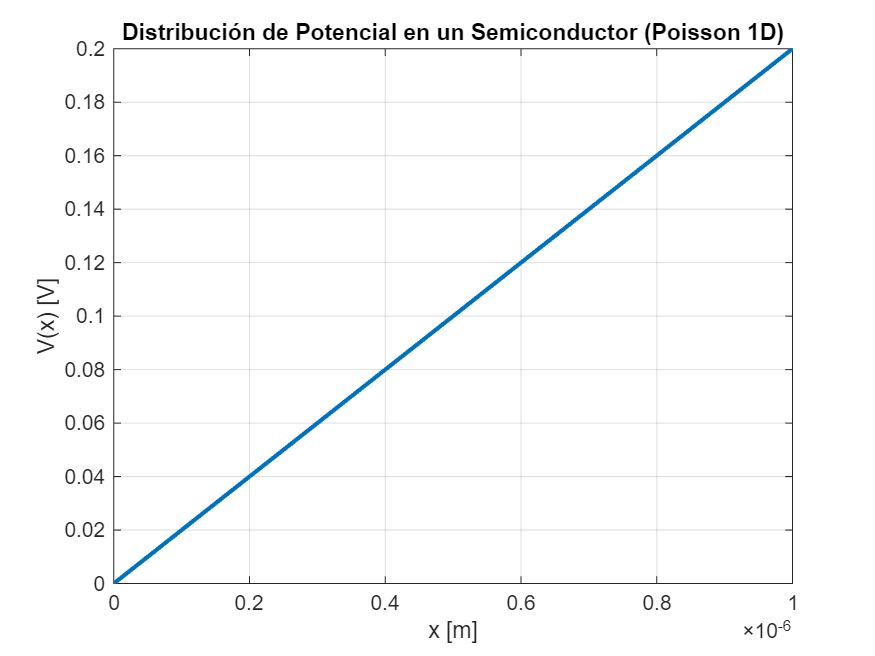

L = 1e-6;            
N = 50;             
h = L/N;

rho0 = 1e-6;          
eps = 11.7*8.854e-12; 

V0 = 0;
VL = 0.2;

A = (1/h^2) * ( diag(2*ones(N-1,1)) + diag(-1*ones(N-2,1),1) + diag(-1*ones(N-2,1),-1) );

b = -(rho0/eps)*ones(N-1,1);
b(1) = b(1) + V0/h^2;
b(end) = b(end) + VL/h^2;
V = A\b;

x = linspace(0,L,N+1);
Vfull = [V0; V; VL];

plot(x, Vfull, 'LineWidth', 2)
xlabel('x [m]')
ylabel('V(x) [V]')
title('Distribución de Potencial en un Semiconductor (Poisson 1D)')
grid on

# Distribución de voltaje en una línea de transmisión (Modelo telegráfico)

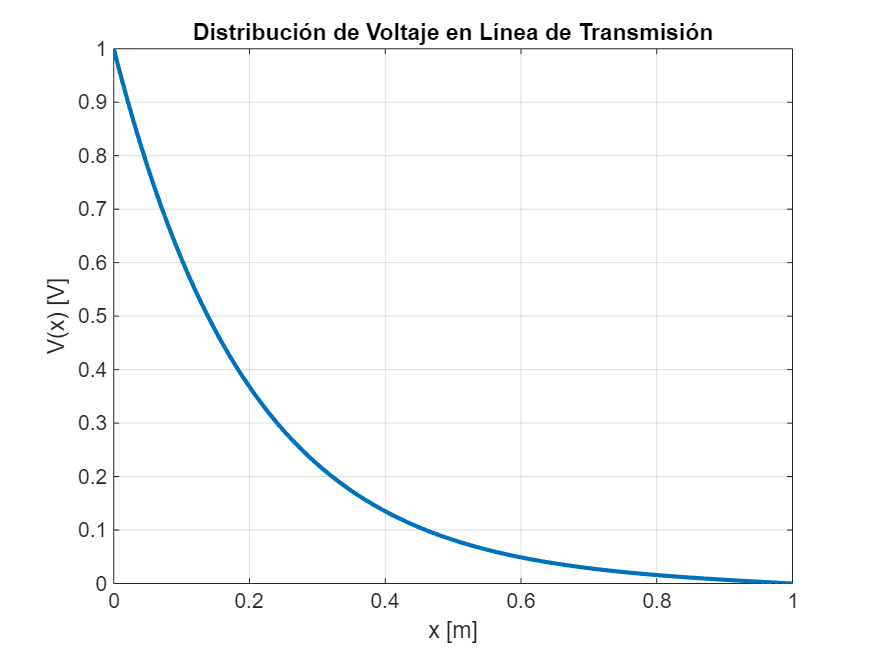

L = 1;            
N = 100;
h = L/N;

k = 5;            
Vin = 1;          
VL = 0;          

A = diag((2 + (k*h)^2)*ones(N-1,1)) ...
    + diag(-1*ones(N-2,1),1) ...
    + diag(-1*ones(N-2,1),-1);

b = zeros(N-1,1);
b(1) = Vin;
b(end) = VL;

V = A\b;
x = linspace(0,L,N+1);
Vfull = [Vin; V; VL];

plot(x, Vfull, 'LineWidth', 2)
xlabel('x [m]')
ylabel('V(x) [V]')
title('Distribución de Voltaje en Línea de Transmisión')
grid on

# `Distribución de temperatura en uncircuito electrónico (Ecuación de calor)`

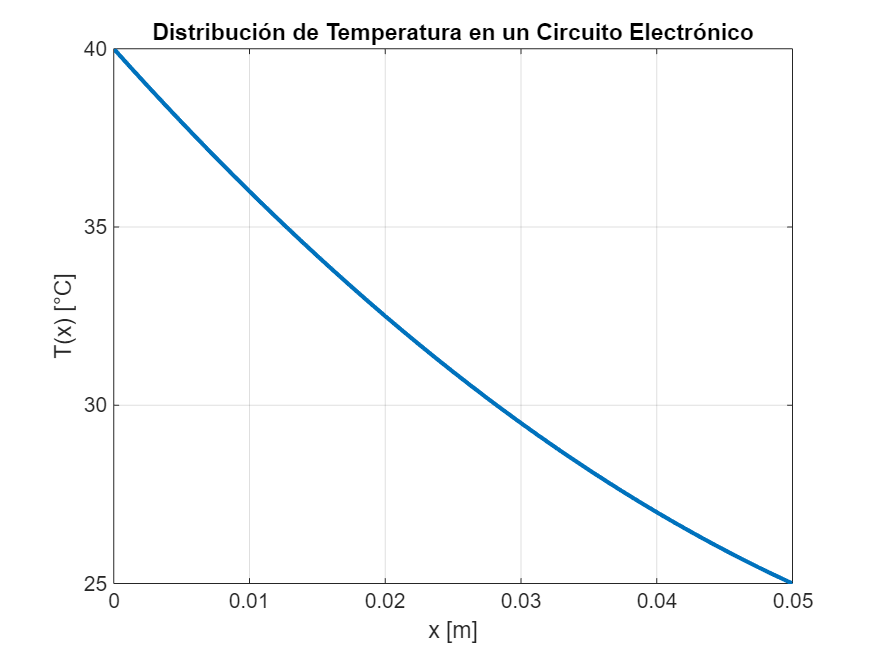

L = 0.05;     
N = 40;
h = L/N;

k = 200;      
Q0 = 1e6;     

T0 = 40;      
TL = 25;      

A = (1/h^2) * ( diag(2*ones(N-1,1)) + diag(-1*ones(N-2,1),1) + diag(-1*ones(N-2,1),-1) );

b = -(Q0/k)*ones(N-1,1);
b(1) = b(1) + T0/h^2;
b(end) = b(end) + TL/h^2;

T = A\b;

x = linspace(0,L,N+1);
Tfull = [T0; T; TL];

plot(x, Tfull, 'LineWidth', 2)
xlabel('x [m]')
ylabel('T(x) [°C]')
title('Distribución de Temperatura en un Circuito Electrónico')
grid on